# Feedforward FOPDT Models

Daniel Anthony Barrett

26 June 2023

Final Year Project (C) 478

Supervisor: Dr Cripwell

### Feedforward FOPDT Models

Fit FOPDT models to the copper solvent extraction model to use for the feedforward controller tuning

## Setup

### MATLAB Simulink

clear;
clc;
gamma_max = 8000; 

### Plot colours

maroon = '#A2142F';
blue   = '#0072BD';

### Step in f_PLSP

### Read data

fPLSP_step_data = readtable('controller_tuning\data\feedforward\fPLSP_step_feedforward.csv');


### Extract data

% model time
fPLSP_step.time = fPLSP_step_data.Time; 

% disturbance data
fPLSP_step.fPLSP = fPLSP_step_data.fPLSP; %v_LE_control; %

% controlled variable data
fPLSP_step.cLO = fPLSP_step_data.cLO_measured; %c_LO_measured; %;


### Preprocess

% deviation variable form
fPLSP_step.fPLSP_prime = fPLSP_step.fPLSP-fPLSP_step.fPLSP(1);
fPLSP_step.cLO_prime = fPLSP_step.cLO-fPLSP_step.cLO(1);

% time step size
fPLSP_step.deltaT = fPLSP_step.time(2) - fPLSP_step.time(1);

% time in hours
fPLSP_step.timeH = fPLSP_step.time/(60*60);


### cLO change

### FOPDT model

for gamma = 0:gamma_max
    
    % system set up
    fPLSP_step.A = [fPLSP_step.cLO_prime((1+gamma):(end-1)), fPLSP_step.fPLSP_prime(1:(end-1-gamma))];
    fPLSP_step.z = fPLSP_step.cLO_prime((2+gamma):end);
    
    % linear regression
    w = fPLSP_step.A\fPLSP_step.z;
    a = w(1);
    b = w(2);
    
    % calculate predicted values
    fPLSP_step.cLO_p = fPLSP_step.A*w;
    
    % calculate MSE 
    fPLSP_step.MSE_cLO(gamma+1) = mean((fPLSP_step.cLO_p - fPLSP_step.z).^2);
    
    % calculate transfer function 
    fPLSP_step.Kp_cLO(gamma+1) = b/(1-a);
    fPLSP_step.tau_cLO(gamma+1) = -fPLSP_step.deltaT/log(a);
    fPLSP_step.theta_cLO(gamma+1) = gamma*fPLSP_step.deltaT;
end


### Find optimal gamma values

% index of optimal gamma
fPLSP_step.opt_gamma_index_cLO = find(fPLSP_step.MSE_cLO == min(fPLSP_step.MSE_cLO));
% optimal transfer function values
fPLSP_step.opt_gamma_cLO = fPLSP_step.opt_gamma_index_cLO - 1;
fPLSP_step.opt_Kp_cLO = fPLSP_step.Kp_cLO(fPLSP_step.opt_gamma_index_cLO);
fPLSP_step.opt_tau_cLO = fPLSP_step.tau_cLO(fPLSP_step.opt_gamma_index_cLO);
fPLSP_step.opt_theta_cLO = fPLSP_step.theta_cLO(fPLSP_step.opt_gamma_index_cLO);


### Simulate transfer function on Simulink

% setup simulink transfer function values
simulink_Kp = fPLSP_step.opt_Kp_cLO;
simulink_tau = fPLSP_step.opt_tau_cLO;
simulink_theta = fPLSP_step.opt_theta_cLO;

% run Simulink model
simulink_input = [fPLSP_step.time fPLSP_step.fPLSP_prime];
simulink_output = sim('controller_tuning\FOPDT_models\FOPDT_model.slx');

% extract Simulink results
fPLSP_step.FOPDT_fit_cLO = simulink_output.results.Data;
fPLSP_step.FOPDT_time_cLO = simulink_output.tout;
fPLSP_step.FOPDT_timeH_cLO = simulink_output.tout/(60*60);


### Plot cLO response to fPLSP change

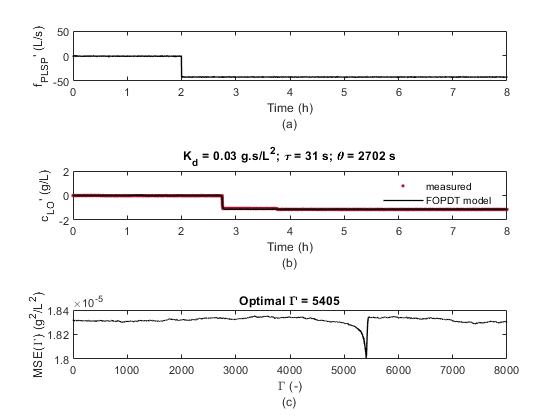

fig = figure(1);

% plot fPLSP
tlo = tiledlayout(fig, 3,1);
ax1 = nexttile(tlo,1);
plot(fPLSP_step.timeH, fPLSP_step.fPLSP_prime, 'k-', 'LineWidth', 1);
xlabel(["Time (h)";"(a)"]);
ylabel("f_{PLSP}' (L/s)");
xlim([0 fPLSP_step.FOPDT_timeH_cLO(end)]);
ylim([-50 50]);

% plot cLO measured
ax2 = nexttile(tlo,2);
plot(fPLSP_step.timeH, fPLSP_step.cLO_prime, '.', 'MarkerSize', 6, 'Color', maroon);
hold on
plot(fPLSP_step.FOPDT_timeH_cLO, fPLSP_step.FOPDT_fit_cLO, 'k-', 'LineWidth', 1);
hold off
fPLSP_step.cLO_title = sprintf('K_d = %.2f g.s/L^{2}; \\tau = %.0f s; \\theta = %.0f s', fPLSP_step.opt_Kp_cLO, fPLSP_step.opt_tau_cLO, fPLSP_step.opt_theta_cLO);
title(fPLSP_step.cLO_title);
legend({'measured', 'FOPDT model'}, 'Location', 'southeast');
legend('boxoff');
xlabel(["Time (h)";"(b)"]);
ylabel("c_{LO}' (g/L)");
xlim([0 fPLSP_step.FOPDT_timeH_cLO(end)]);
ylim([-2 2]);

% plot MSE
ax3 = nexttile(tlo,3);
plot([0:gamma_max], fPLSP_step.MSE_cLO, 'k-', 'LineWidth', 1);
fPLSP_step.cLO_MSE_title = sprintf('Optimal \\Gamma = %.0f', fPLSP_step.opt_gamma_cLO);
title(fPLSP_step.cLO_MSE_title);
xlabel(["\Gamma (-)"; "(c)"]);
ylabel("MSE(\Gamma) (g^{2}/L^{2})");
xlim([0 gamma_max]);

% save figure
print('controller_tuning/output/feedforward/fPLSP_step_cLO_model', '-dpng', '-r600');

### Step in f_PLSS

### Read data

fPLSS_step_data = readtable('controller_tuning\data\feedforward\fPLSS_step_feedforward.csv');


### Extract data

% model time
fPLSS_step.time = fPLSS_step_data.Time; 

% disturbance data
fPLSS_step.fPLSS = fPLSS_step_data.fPLSS; %v_LE_control; %

% controlled variable data
fPLSS_step.cLO = fPLSS_step_data.cLO_measured; %c_LO_measured; %;


### Preprocess

% deviation variable form
fPLSS_step.fPLSS_prime = fPLSS_step.fPLSS-fPLSS_step.fPLSS(1);
fPLSS_step.cLO_prime = fPLSS_step.cLO-fPLSS_step.cLO(1);

% time step size
fPLSS_step.deltaT = fPLSS_step.time(2) - fPLSS_step.time(1);

% time in hours
fPLSS_step.timeH = fPLSS_step.time/(60*60);


### cLO change

### FOPDT model

for gamma = 0:gamma_max
    
    % system set up
    fPLSS_step.A = [fPLSS_step.cLO_prime((1+gamma):(end-1)), fPLSS_step.fPLSS_prime(1:(end-1-gamma))];
    fPLSS_step.z = fPLSS_step.cLO_prime((2+gamma):end);
    
    % linear regression
    w = fPLSS_step.A\fPLSS_step.z;
    a = w(1);
    b = w(2);
    
    % calculate predicted values
    fPLSS_step.cLO_p = fPLSS_step.A*w;
    
    % calculate MSE 
    fPLSS_step.MSE_cLO(gamma+1) = mean((fPLSS_step.cLO_p - fPLSS_step.z).^2);
    
    % calculate transfer function 
    fPLSS_step.Kp_cLO(gamma+1) = b/(1-a);
    fPLSS_step.tau_cLO(gamma+1) = -fPLSS_step.deltaT/log(a);
    fPLSS_step.theta_cLO(gamma+1) = gamma*fPLSS_step.deltaT;
end


### Find optimal gamma values

% index of optimal gamma
fPLSS_step.opt_gamma_index_cLO = find(fPLSS_step.MSE_cLO == min(fPLSS_step.MSE_cLO));
% optimal transfer function values
fPLSS_step.opt_gamma_cLO = fPLSS_step.opt_gamma_index_cLO - 1;
fPLSS_step.opt_Kp_cLO = fPLSS_step.Kp_cLO(fPLSS_step.opt_gamma_index_cLO);
fPLSS_step.opt_tau_cLO = fPLSS_step.tau_cLO(fPLSS_step.opt_gamma_index_cLO);
fPLSS_step.opt_theta_cLO = fPLSS_step.theta_cLO(fPLSS_step.opt_gamma_index_cLO);


### Simulate transfer function on Simulink

% setup simulink transfer function values
simulink_Kp = fPLSS_step.opt_Kp_cLO;
simulink_tau = fPLSS_step.opt_tau_cLO;
simulink_theta = fPLSS_step.opt_theta_cLO;

% run Simulink model
simulink_input = [fPLSS_step.time fPLSS_step.fPLSS_prime];
simulink_output = sim('controller_tuning\FOPDT_models\FOPDT_model.slx');

% extract Simulink results
fPLSS_step.FOPDT_fit_cLO = simulink_output.results.Data;
fPLSS_step.FOPDT_time_cLO = simulink_output.tout;
fPLSS_step.FOPDT_timeH_cLO = simulink_output.tout/(60*60);


### Plot cLO response to fPLSS change

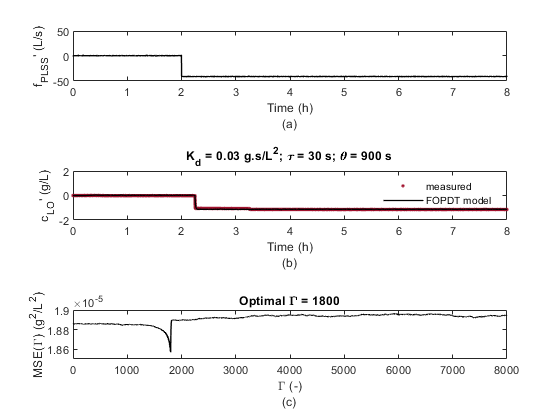

fig = figure(2);

% plot fPLSS
tlo = tiledlayout(fig, 3,1);
ax1 = nexttile(tlo,1);
plot(fPLSS_step.timeH, fPLSS_step.fPLSS_prime, 'k-', 'LineWidth', 1);
xlabel(["Time (h)";"(a)"]);
ylabel("f_{PLSS}' (L/s)");
xlim([0 fPLSS_step.FOPDT_timeH_cLO(end)]);
ylim([-50 50]);

% plot cLO measured
ax2 = nexttile(tlo,2);
plot(fPLSS_step.timeH, fPLSS_step.cLO_prime, '.', 'MarkerSize', 6, 'Color', maroon);
hold on
plot(fPLSS_step.FOPDT_timeH_cLO, fPLSS_step.FOPDT_fit_cLO, 'k-', 'LineWidth', 1);
hold off
fPLSS_step.cLO_title = sprintf('K_d = %.2f g.s/L^{2}; \\tau = %.0f s; \\theta = %.0f s', fPLSS_step.opt_Kp_cLO, fPLSS_step.opt_tau_cLO, fPLSS_step.opt_theta_cLO);
title(fPLSS_step.cLO_title);
legend({'measured', 'FOPDT model'}, 'Location', 'southeast');
legend('boxoff');
xlabel(["Time (h)";"(b)"]);
ylabel("c_{LO}' (g/L)");
xlim([0 fPLSS_step.FOPDT_timeH_cLO(end)]);
ylim([-2 2]);

% plot MSE
ax3 = nexttile(tlo,3);
plot([0:gamma_max], fPLSS_step.MSE_cLO, 'k-', 'LineWidth', 1);
fPLSS_step.cLO_MSE_title = sprintf('Optimal \\Gamma = %.0f', fPLSS_step.opt_gamma_cLO);
title(fPLSS_step.cLO_MSE_title);
xlabel(["\Gamma (-)"; "(c)"]);
ylabel("MSE(\Gamma) (g^{2}/L^{2})");
xlim([0 gamma_max]);

% save figure
print('controller_tuning/output/feedforward/fPLSS_step_cLO_model', '-dpng', '-r600');

### Step in c_PLS

### Read data

cPLS_step_data = readtable('controller_tuning\data\feedforward\cPLS_step_feedforward.csv');

### Extract data

% model time
cPLS_step.time = cPLS_step_data.Time; 

% disturbance data
cPLS_step.cPLS = cPLS_step_data.cPLS; %v_LE_control; %

% controlled variable data
cPLS_step.cLO = cPLS_step_data.cLO_measured; %c_LO_measured; %;

### Preprocess

% deviation variable form
cPLS_step.cPLS_prime = cPLS_step.cPLS-cPLS_step.cPLS(1);
cPLS_step.cLO_prime = cPLS_step.cLO-cPLS_step.cLO(1);

% time step size
cPLS_step.deltaT = cPLS_step.time(2) - cPLS_step.time(1);

% time in hours
cPLS_step.timeH = cPLS_step.time/(60*60);

### cLO change

### FOPDT model

for gamma = 0:gamma_max
    
    % system set up
    cPLS_step.A = [cPLS_step.cLO_prime((1+gamma):(end-1)), cPLS_step.cPLS_prime(1:(end-1-gamma))];
    cPLS_step.z = cPLS_step.cLO_prime((2+gamma):end);
    
    % linear regression
    w = cPLS_step.A\cPLS_step.z;
    a = w(1);
    b = w(2);
    
    % calculate predicted values
    cPLS_step.cLO_p = cPLS_step.A*w;
    
    % calculate MSE 
    cPLS_step.MSE_cLO(gamma+1) = mean((cPLS_step.cLO_p - cPLS_step.z).^2);
    
    % calculate transfer function 
    cPLS_step.Kp_cLO(gamma+1) = b/(1-a);
    cPLS_step.tau_cLO(gamma+1) = -cPLS_step.deltaT/log(a);
    cPLS_step.theta_cLO(gamma+1) = gamma*cPLS_step.deltaT;
end

### Find optimal gamma values

% index of optimal gamma
cPLS_step.opt_gamma_index_cLO = find(cPLS_step.MSE_cLO == min(cPLS_step.MSE_cLO));
% optimal transfer function values
cPLS_step.opt_gamma_cLO = cPLS_step.opt_gamma_index_cLO - 1;
cPLS_step.opt_Kp_cLO = cPLS_step.Kp_cLO(cPLS_step.opt_gamma_index_cLO);
cPLS_step.opt_tau_cLO = cPLS_step.tau_cLO(cPLS_step.opt_gamma_index_cLO);
cPLS_step.opt_theta_cLO = cPLS_step.theta_cLO(cPLS_step.opt_gamma_index_cLO);

### Simulate transfer function on Simulink

% setup simulink transfer function values
simulink_Kp = cPLS_step.opt_Kp_cLO;
simulink_tau = cPLS_step.opt_tau_cLO;
simulink_theta = cPLS_step.opt_theta_cLO;

% run Simulink model
simulink_input = [cPLS_step.time cPLS_step.cPLS_prime];
simulink_output = sim('controller_tuning\FOPDT_models\FOPDT_model.slx');

% extract Simulink results
cPLS_step.FOPDT_fit_cLO = simulink_output.results.Data;
cPLS_step.FOPDT_time_cLO = simulink_output.tout;
cPLS_step.FOPDT_timeH_cLO = simulink_output.tout/(60*60);

### Plot cLO response to cPLS change

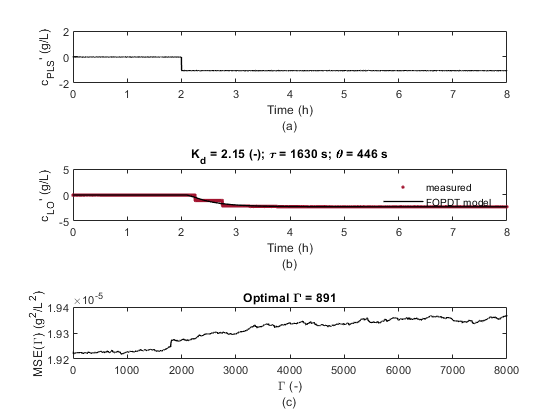

fig = figure(3);

% plot cPLS
tlo = tiledlayout(fig, 3,1);
ax1 = nexttile(tlo,1);
plot(cPLS_step.timeH, cPLS_step.cPLS_prime, 'k-', 'LineWidth', 1);
xlabel(["Time (h)";"(a)"]);
ylabel("c_{PLS}' (g/L)");
xlim([0 cPLS_step.FOPDT_timeH_cLO(end)]);
ylim([-2 2]);

% plot cLO measured
ax2 = nexttile(tlo,2);
plot(cPLS_step.timeH, cPLS_step.cLO_prime, '.', 'MarkerSize', 6, 'Color', maroon);
hold on
plot(cPLS_step.FOPDT_timeH_cLO, cPLS_step.FOPDT_fit_cLO, 'k-', 'LineWidth', 1);
hold off
cPLS_step.cLO_title = sprintf('K_d = %.2f (-); \\tau = %.0f s; \\theta = %.0f s', cPLS_step.opt_Kp_cLO, cPLS_step.opt_tau_cLO, cPLS_step.opt_theta_cLO);
title(cPLS_step.cLO_title);
legend({'measured', 'FOPDT model'}, 'Location', 'southeast');
legend('boxoff');
xlabel(["Time (h)";"(b)"]);
ylabel("c_{LO}' (g/L)");
xlim([0 cPLS_step.FOPDT_timeH_cLO(end)]);
ylim([-5 5]);

% plot MSE
ax3 = nexttile(tlo,3);
plot([0:gamma_max], cPLS_step.MSE_cLO, 'k-', 'LineWidth', 1);
cPLS_step.cLO_MSE_title = sprintf('Optimal \\Gamma = %.0f', cPLS_step.opt_gamma_cLO);
title(cPLS_step.cLO_MSE_title);
xlabel(["\Gamma (-)"; "(c)"]);
ylabel("MSE(\Gamma) (g^{2}/L^{2})");
xlim([0 gamma_max]);

% save figure
print('controller_tuning/output/feedforward/cPLS_step_cLO_model', '-dpng', '-r600');

### Step in c_PLS

### Read data

cLE_step_data = readtable('controller_tuning\data\feedforward\cLE_step_feedforward.csv');

### Extract data

% model time
cLE_step.time = cLE_step_data.Time; 

% disturbance data
cLE_step.cLE = cLE_step_data.cLE; %v_LE_control; %

% controlled variable data
cLE_step.cRE = cLE_step_data.cRE_measured; %c_LO_measured; %;

### Preprocess

% deviation variable form
cLE_step.cLE_prime = cLE_step.cLE-cLE_step.cLE(1);
cLE_step.cRE_prime = cLE_step.cRE-cLE_step.cRE(1);

% time step size
cLE_step.deltaT = cLE_step.time(2) - cLE_step.time(1);

% time in hours
cLE_step.timeH = cLE_step.time/(60*60);

### cRE change

### FOPDT model

for gamma = 0:gamma_max
    
    % system set up
    cLE_step.A = [cLE_step.cRE_prime((1+gamma):(end-1)), cLE_step.cLE_prime(1:(end-1-gamma))];
    cLE_step.z = cLE_step.cRE_prime((2+gamma):end);
    
    % linear regression
    w = cLE_step.A\cLE_step.z;
    a = w(1);
    b = w(2);
    
    % calculate predicted values
    cLE_step.cRE_p = cLE_step.A*w;
    
    % calculate MSE 
    cLE_step.MSE_cRE(gamma+1) = mean((cLE_step.cRE_p - cLE_step.z).^2);
    
    % calculate transfer function 
    cLE_step.Kp_cRE(gamma+1) = b/(1-a);
    cLE_step.tau_cRE(gamma+1) = -cLE_step.deltaT/log(a);
    cLE_step.theta_cRE(gamma+1) = gamma*cLE_step.deltaT;
end

### Find optimal gamma values

% index of optimal gamma
cLE_step.opt_gamma_index_cRE = find(cLE_step.MSE_cRE == min(cLE_step.MSE_cRE));
% optimal transfer function values
cLE_step.opt_gamma_cRE = cLE_step.opt_gamma_index_cRE - 1;
cLE_step.opt_Kp_cRE = cLE_step.Kp_cRE(cLE_step.opt_gamma_index_cRE);
cLE_step.opt_tau_cRE = cLE_step.tau_cRE(cLE_step.opt_gamma_index_cRE);
cLE_step.opt_theta_cRE = cLE_step.theta_cRE(cLE_step.opt_gamma_index_cRE);

### Simulate transfer function on Simulink

% setup simulink transfer function values
simulink_Kp = cLE_step.opt_Kp_cRE;
simulink_tau = cLE_step.opt_tau_cRE;
simulink_theta = cLE_step.opt_theta_cRE;

% run Simulink model
simulink_input = [cLE_step.time cLE_step.cLE_prime];
simulink_output = sim('controller_tuning\FOPDT_models\FOPDT_model.slx');

% extract Simulink results
cLE_step.FOPDT_fit_cRE = simulink_output.results.Data;
cLE_step.FOPDT_time_cRE = simulink_output.tout;
cLE_step.FOPDT_timeH_cRE = simulink_output.tout/(60*60);

### Plot cRE response to cLE change

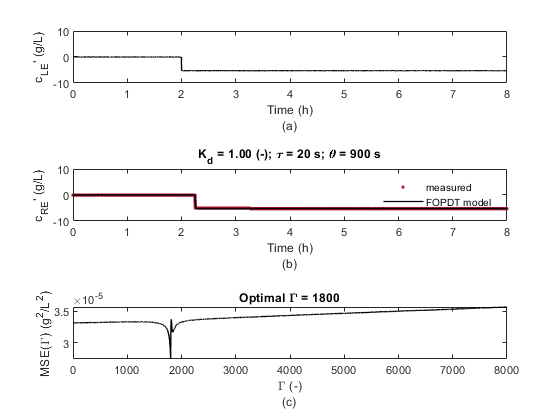

fig = figure(4);

% plot cLE
tlo = tiledlayout(fig, 3,1);
ax1 = nexttile(tlo,1);
plot(cLE_step.timeH, cLE_step.cLE_prime, 'k-', 'LineWidth', 1);
xlabel(["Time (h)";"(a)"]);
ylabel("c_{LE}' (g/L)");
xlim([0 cLE_step.FOPDT_timeH_cRE(end)]);
ylim([-10 10]);

% plot cRE measured
ax2 = nexttile(tlo,2);
plot(cLE_step.timeH, cLE_step.cRE_prime, '.', 'MarkerSize', 6, 'Color', maroon);
hold on
plot(cLE_step.FOPDT_timeH_cRE, cLE_step.FOPDT_fit_cRE, 'k-', 'LineWidth', 1);
hold off
cLE_step.cRE_title = sprintf('K_d = %.2f (-); \\tau = %.0f s; \\theta = %.0f s', cLE_step.opt_Kp_cRE, cLE_step.opt_tau_cRE, cLE_step.opt_theta_cRE);
title(cLE_step.cRE_title);
legend({'measured', 'FOPDT model'}, 'Location', 'southeast');
legend('boxoff');
xlabel(["Time (h)";"(b)"]);
ylabel("c_{RE}' (g/L)");
xlim([0 cLE_step.FOPDT_timeH_cRE(end)]);
ylim([-10 10]);

% plot MSE
ax3 = nexttile(tlo,3);
plot([0:gamma_max], cLE_step.MSE_cRE, 'k-', 'LineWidth', 1);
cLE_step.cRE_MSE_title = sprintf('Optimal \\Gamma = %.0f', cLE_step.opt_gamma_cRE);
title(cLE_step.cRE_MSE_title);
xlabel(["\Gamma (-)"; "(c)"]);
ylabel("MSE(\Gamma) (g^{2}/L^{2})");
xlim([0 gamma_max]);

% save figure
print('controller_tuning/output/feedforward/cLE_step_cRE_model', '-dpng', '-r600');